## Tensor Kronecker Product Singular Value Decomposition (TKPSVD)

Consider the tensor $\underline{\mathbf{X}} \in C^{I_1 \times I_2 \times \cdots \times I_N }$ that can be expressed as


$$\underline{\mathbf{X}} =\sum_{r=1}^R \lambda_r \;{\underline{\mathbf{A}} }_{\;\;\;r}^{\left(D\right)} \otimes {\underline{\mathbf{A}} }_{\;\;\;r}^{\left(D-1\right)} \otimes \cdots \otimes {\underline{\mathbf{A}} }_{\;\;\;r}^{\left(1\right)}$$


where $R$ is the Kronecker rank, $D$ is the degree of decomposition, and the tensor ${\underline{\mathbf{A}} }_{\;\;\;r}^{\left(d\right)} \in C^{I_1^{\left(d\right)} \times I_2^{\left(d\right)} \times \cdots \times I_N^{\left(d\right)} }$satisfies


$${\left\|{\underline{\mathbf{A}} }_{\;\;\;r}^{\left(d\right)} \left(i\right)\right\|}_F^{\;} =1$$


and


$$\prod_{d=1}^D I_n^{\left(d\right)} =I_n$$


For $R=1$, $d=3$, ${\underline{\mathbf{A}} }_{\;\;}^{\left(1\right)} \in C^{10\times 4\times 2}$, ${\underline{\mathbf{A}} }_{\;\;}^{\left(2\right)} \in C^{5\times 2\times 2}$, ${\underline{\mathbf{A}} }_{\;\;}^{\left(3\right)} \in C^{2\times 2\times 2}$. The tensor $\underline{\mathbf{X}}$ is given bt


$$\underline{\mathbf{X}} =\lambda \;{\underline{\mathbf{A}} }_{\;\;\;}^{\left(3\right)} \otimes {\underline{\mathbf{A}} }_{\;\;\;}^{\left(3\right)} \otimes {\underline{\mathbf{A}} }_{\;\;\;}^{\left(2\right)} \in C^{100\times 16\times 8}$$


The Tensor Kronecker Product Singular Value Decomposition aims to reduce the following cost function


$$\left({\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(1\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(2\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(3\right)} \right)=\min_{{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(1\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(2\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(3\right)} } {\left\|\underline{\mathbf{X}} -\underline{\hat{\mathbf{X}} } \right\|}_F^2 =\min_{{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(1\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(2\right)} ,{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(3\right)} } {\left\|\underline{\mathbf{X}} -\lambda \;{\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(1\right)} \otimes {\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(2\right)} \otimes {\underline{\hat{\mathbf{A}} } }_{\;\;}^{\left(3\right)} \right\|}_F^2$$


- TKPSVD is a direct generalization of the KPSVD to an arbitrary number of KP factors and to arbitrary N-order tensors.

- The user of the TKPSVD algorithm is completely free to choose the degree $D$ and the dimensions $I_n^{\left(d\right)}$ for $1\le n\le N,1\le d\le D$, as long as they satisfy the above equation.

- When $D=2$ and $N=2$, TKPSVD reduces to the KPSVD

Just as the KPSVD, the tensor $\underline{\mathbf{X}}$ shall be reordered to the equality makes sense. Let us define $\underline{\tilde{\mathbf{X}} }$ as the ordered tensor that can be written in CP fasion, for a generic kronecker rank, we have


$$\underline{\tilde{\mathbf{X}} } =\sum_{r=1}^R \lambda_r {{\mathbf{a}}_r }^{\left(1\right)} \circ {{\mathbf{a}}_r }^{\left(2\right)} \circ {{\mathbf{a}}_r }^{\left(3\right)}$$


for $R=1$


$$\underline{\tilde{\mathbf{X}} } =\lambda \;{\mathbf{a}}^{\left(1\right)} \circ {\mathbf{a}}^{\left(2\right)} \circ {\mathbf{a}}^{\left(3\right)}$$


where ${\mathbf{a}}^{\left(d\right)} =\textrm{vec}\left({\mathbf{A}}^{\left(d\right)} \right)$

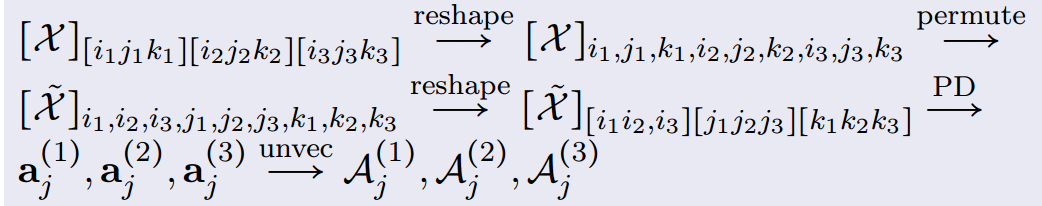

## Problem 1

load tkpsvd.mat tenX sigma tenA1_orginal tenA2_orginal tenA3_orginal

all_I_n_d = [10, 4, 2;...
              5, 2, 2;...
              2, 2, 2]

all_I_n_d =     10     4     2
     5     2     2
     2     2     2


[all_A, lambda] = tkpsvd(tenX, all_I_n_d);
all_A_flipped = flip(all_A)

all_A_flipped = 1×3 cell array
    {2×2×2 double}    {5×2×2 double}    {10×4×2 double}


% reconstructing tenX_hat
tenX_hat = lambda*tenkron(all_A_flipped{:});

% normalized squared erro
nse = norm(tensor(tenX - tenX_hat))/ norm(tensor(tenX))

nse = 4.8365e-16

## Problem 2

Let us define

$\underline{{\mathbf{X}}_0 } ={\underline{\mathbf{A}} }^{\left(1\right)} \otimes {\underline{\mathbf{A}} }^{\left(2\right)} \otimes {\underline{\mathbf{A}} }^{\left(3\right)} \in C^{100\times 16\times 8}$,

being${\underline{\mathbf{A}} }^{\left(1\right)} \in C^{10\times 4\times 2}$, ${\underline{\mathbf{A}} }^{\left(2\right)} \in C^{5\times 2\times 2}$, ${\underline{\mathbf{A}} }^{\left(3\right)} \in C^{2\times 2\times 2}$.

Consider a noisy term, $\underline{\mathbf{V}}$, with same dimension of $\underline{{\mathbf{X}}_0 }$, whose components come from a normal distribution with the same statistics. Let us further define $\underline{\mathbf{X}} =\underline{{\mathbf{X}}_0 } +\alpha \underline{\mathbf{V}}$ as the noisy version of $\underline{{\mathbf{X}}_0 }$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\textrm{SNR}}_{\textrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|\underline{{\mathbf{X}}_0 } \right\|}_F^2 }{{\left\|\alpha \underline{\mathbf{V}} \right\|}_F^2 }\right)\to \alpha =\frac{{\left\|\underline{{\mathbf{X}}_0 } \right\|}_F^{\;} }{{\left\|\underline{\mathbf{V}} \right\|}_F^{\;} }\sqrt{{10}^{-\frac{{\textrm{SNR}}_{\textrm{dB}} }{10}} }$$


For the SNR for the range $\left\lbrack \begin{array}{ccccccc}
0 & 5 & 10 & 15 & 20 & 25 & 30
\end{array}\right\rbrack$ dB , find the estimates ${\underline{\hat{\mathbf{A}} } }^{\left(1\right)}$, ${\underline{\hat{\mathbf{A}} } }^{\left(2\right)}$ and ${\underline{\hat{\mathbf{A}} } }^{\left(3\right)}$ using the TKPSVD method. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|{\mathbf{X}}_0 \left(i\right)-\underline{\hat{\mathbf{X}} } \left(i\right)\right\|}_F^2 }{{\left\|{\mathbf{X}}_0 \left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The values ${\underline{\mathbf{A}} }^{\left(1\right)}$, ${\underline{\mathbf{A}} }^{\left(2\right)}$, ${\underline{\mathbf{A}} }^{\left(3\right)}$, and $\underline{\mathbf{V}}$ are generated randomly for each experiment.

max = 1e1;
all_snr = 0:5:30;
all_nmse = zeros(1,length(all_snr));
for snr=all_snr
    nmse = 0;
    for i=1:max
        % generating A1, A2, A3
        A1 = randn([10,4,2]);
        A2 = randn([ 5,2,2]);
        A3 = randn([ 2,2,2]);
        
        % generating tenX
        tenX0 = tenkron(A3, A2, A1);
        tenV = randn(size(tenX0));
        alpha = sqrt(10^(-snr/10))* norm(tensor(tenX0))/ norm(tensor(tenV));
        tenX = tenX0 + alpha*tenV;
        [all_A, lambda] = tkpsvd(tenX, all_I_n_d);
        all_A_flipped = flip(all_A);
        
        % generating tenX_hat
        tenX_hat = lambda*tenkron(all_A_flipped{:});
        
        % computing the nmse_loop
        nmse_loop = norm(tensor(tenX0 - tenX_hat))/ norm(tensor(tenX0));
        nmse = nmse + nmse_loop;
    end
    all_nmse(all_snr==snr) = nmse/max;
end

#### Ploting the results

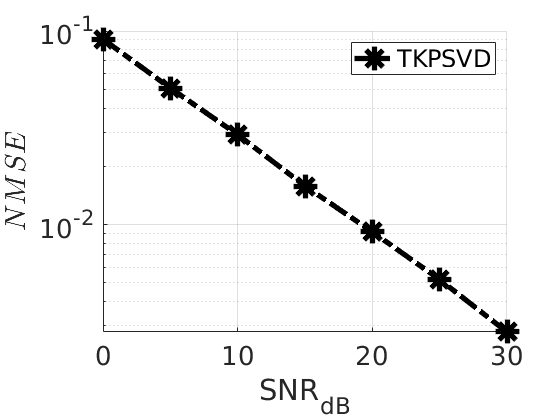

color_set = ["red", "black"];
fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
grid on;
hold on;
plot(all_snr, all_nmse, 'LineWidth', 4, 'Color', "black","LineStyle","-.","Marker","*","MarkerSize",18);
legend('TKPSVD');
hold off;

function [all_A, lambda] = tkpsvd(tenX, all_I_n_d)
% all_I_n_d is a D x N matrix -> the i-th row defines the dimensionality of the A^(i) 

% instance of X tilde
tenX_tilde_9 = zeros(reshape(all_I_n_d,1,[]));
% creating all index of X tilde 9
all_index = cellfun(@(x)1:x, num2cell(reshape(all_I_n_d.', 1, [])), 'UniformOutput', false);
all_index = combvec(all_index{:});
all_index = cellfun(@(x)x.', num2cell(all_index,1), 'UniformOutput', false);
for index=all_index
    % index      = [i1, i2, i3, j1, j2, j3, k1, k2, k3]
    % indeces_X3 = [i1+I1*(j1-1)+I1J1(k1-1), i2+I2*(j2-1)+I2J2(k2-1), i3+I3*(j3-1)+I3J3(k3-1)]
    % indeces_X9 = [i1, j1, k1, i2, j2, k2, i3, j3, k3]
    indeces_X3 = cellfun(@(x)x(1:3)+all_I_n_d(1,:).*(x(4:6)-1)+all_I_n_d(1,:).*all_I_n_d(2,:).*(x(7:9)-1), index, 'UniformOutput', false);
    indeces_X3 = num2cell(indeces_X3{:});
    indeces_X9 = index{1}([1:3:9 2:3:9 3:3:9]);
    indeces_X9 = num2cell(indeces_X9);
    % X_tilde(i_1^(1), i_1^(2), ..., i_1^(9)) = X (i_1^(1)*i_1^(2)*i_1^(3), i_1^(4)*i_1^(5)*i_1^(6), i_1^(7)*i_1^(8)*i_1^(9))
    tenX_tilde_9(indeces_X9{:}) = tenX(indeces_X3{:});
end

% tenX_tilde_9_permuted has indices [i1, i2, i3, j1, j2, j3, k1, k2, k3]
tenX_tilde_9_permuted = permute(tenX_tilde_9, [1:3:9 2:3:9 3:3:9]);

% creating all index of X tilde 3
tenX_tilde_3 = zeros(prod(size(tenX_tilde_9_permuted, 1:3)), prod(size(tenX_tilde_9_permuted, 4:6)), prod(size(tenX_tilde_9_permuted, 7:9)));

for index=all_index
    % index                 = [i1, i2, i3, j1, j2, j3, k1, k2, k3]
    % indeces_X9_tilde      = [i1, i2, i3, j1, j2, j3, k1, k2, k3]
    % indeces_X3_tilde      = [i1+I1*(i2-1)+I1I2(i3-1), j1+J1*(j2-1)+J1J2(j3-1), k3+K1*(k2-1)+K1K2(k3-1)]
    indeces_X9_tilde = num2cell(index{1});
    indeces_X3_tilde = cellfun(@(x)x(1:3:9)+(all_I_n_d(:,1).').*(x(2:3:9)-1)+(all_I_n_d(:,1).').*(all_I_n_d(:,2).').*(x(3:3:9)-1), index, 'UniformOutput', false);
    indeces_X3_tilde = num2cell(indeces_X3_tilde{:});
    tenX_tilde_3(indeces_X3_tilde{:}) = tenX_tilde_9_permuted(indeces_X9_tilde{:});
end

% tenX_tilde_3 shall be a 1-rank tensor
[lambda, all_a, ~, ~] = als(tenX_tilde_3, 1);
all_A = cellfun(@reshape, all_a, mat2cell(all_I_n_d, ones(1,3)).', 'UniformOutput', false);
end